# Example 13.1: Three-Channel Hybrid Solution

Nicholas O'Donoughue 1 July 2019

`Consider a three-channel hybrid solution with sensors spaced 10 km abreast (side-by-side) and traveling in formation at a velocity of 100 m/s. Each platform contains a ``DF`` sensor, and time/frequency measurements for ``TDOA`` and ``FDOA`` estimation. Assuming all measurements are independent with `$$\sigma_\psi=200$$ `mrad``, `$$\sigma_\tau=100$$ `ns``, and $\sigma_f=10$ Hz, and that ``TDOA`` and ``FDOA`` utilize a common reference sensor. Construct the measurement and estimate source location for an emitter that is 30 km in front and 30 km to the side of the central sensor, with a carrier frequency of `$$f_0 = 1$$` GHz.`

## Solution

`To begin, we set up the scenario geometry.`

sensor_spacing = 10*1e3; % meters
sensor_vel     = 100; % meters/second
sensor_heading = pi/2; % radians
num_sensors    = 3;
ref_sensor_idx = 2; assert(ref_sensor_idx>0 && ref_sensor_idx<=num_sensors,'Bad reference sensor index.');

x_sensor = [sensor_spacing * ((0:num_sensors-1)-(num_sensors-1)/2);
            zeros(1,num_sensors)];
v_sensor = sensor_vel * [cos(sensor_heading);sin(sensor_heading)]*ones(1,num_sensors);

x_source = [30; 30]*1e3; % Transmitter/source [m]
x_init   = [0; 10]*1e3; % Initial guess [m]

We are assuming independent measurements for the AOA, and a common reference sensor for both TDOA and FDOA, so the former is diagonal, and the latter are both a diagonal added to a common error term. We will discuss the feasibility of this (that TDOA and FDOA measurements are independent) later in this chapter.

% Sensor Performance
source_freq = 1e9; % Hz
angle_err   = 0.2; % rad
time_err    = 1e-7; % sec
freq_err    = 3; % Hz
rng_err = utils.constants.c*time_err; % m
rng_rate_err = freq_err * utils.constants.c/source_freq; % m/s

% Perfect Measurement
z = hybrid.measurement(x_sensor,x_sensor,x_sensor,v_sensor,x_source,ref_sensor_idx,ref_sensor_idx);

% Error Covariance Matrices
C_psi = (angle_err)^2 * eye(num_sensors);
C_roa = rng_err^2 * eye(num_sensors);
C_rroa = rng_rate_err^2 * eye(num_sensors);
C_full_msmt = blkdiag(C_psi,C_roa,C_rroa); % Measurement level covariance matrix

% Parse the TDOA and FDOA reference indices together
% These reference/test indices are used for TDOA and FDOA sensor pair
% measurements.  This parsing format ensures consistent bookkeeping across
% the various algorithms (the solvers, CRLB, and measurement generator).
[test_idx, ref_idx] = utils.parseReferenceSensor(ref_sensor_idx,num_sensors);
test_idx_vec = cat(2,test_idx, num_sensors + test_idx);
ref_idx_vec = cat(2,ref_idx, num_sensors + ref_idx);

% We assume the AOA is independent of TDOA/FDOA, so they're generated
% separately.
C_tfdoa = blkdiag(C_roa,C_rroa);
C_tilde = blkdiag(C_psi, utils.resampleCovMtx(C_tfdoa, test_idx_vec, ref_idx_vec));

`Next, we generate noisy measurements based on the ``covariance`` matrix `$\texttt{C\_full}$`, and apply the available solvers on each noisy data set; `$\texttt{hybrid.lsSoln}$` and `$\texttt{hybrid.gdSoln}$`.`

% Error Vectors
num_monte_carlo = 1000;
L = chol(C_tilde,'lower'); % Generate noise using the resampled covariance matrix
num_msmts = size(L,1);
noise = L*randn(num_msmts,num_monte_carlo);

% Set up optimization parameters
epsilon =       100; % Stopping condition for iterative solvers
num_iters =     200; % Maxinum number of iterations for iterative solvers
alpha =         0.3; % Parameter for gradient descent
beta =          0.6; % Parameter for gradient descent
search_size =  [50; 50]; % Search Grid Size
grid_res =      100; % Resolution of the search grid
plot_progress = false;

% Perform Monte Carlo Loop
x_ls = zeros(2,num_iters,num_monte_carlo);
x_grad = zeros(2,num_iters,num_monte_carlo);
x_bf = zeros(2,num_monte_carlo);

fprintf('Performing Monte Carlo simulation...\n');

Performing Monte Carlo simulation...


warning('off','MATLAB:nearlySingularMatrix'); % We know the problem is ill-defined, deactivate the warning
for idx_mc = 1:num_monte_carlo
    fprintf('.');
    if mod(idx_mc,50)==0
        fprintf(' (%d/%d)\n',idx_mc,num_monte_carlo);
    end

    % Add noise to measurement
    zeta = z+noise(:,idx_mc);

    % Solvers
    % Note that we pass the measurement level covariance matrices in; the
    % solvers parse those, using the tdoa and fdoa reference sensor indices
    % provided and generate a matrix that matches C_tilde.
    [~,x_ls(:,:,idx_mc)] = hybrid.lsSoln(x_sensor,x_sensor,x_sensor,v_sensor,zeta,C_full_msmt,x_init,[],num_iters,true,plot_progress,ref_sensor_idx,ref_sensor_idx);
    [~,x_grad(:,:,idx_mc)] = hybrid.gdSoln(x_sensor,x_sensor,x_sensor,v_sensor,zeta,C_full_msmt,x_init,alpha,beta,[],num_iters,true,plot_progress,ref_sensor_idx,ref_sensor_idx);
    x_bf(:,idx_mc) = hybrid.bfSoln(x_sensor,x_sensor,x_sensor,v_sensor,zeta,C_full_msmt,x_init,2*max(x_source(:)),grid_res,ref_sensor_idx,ref_sensor_idx);
end

..................................................

 (50/1000)


..................................................

 (100/1000)


......................................

warning('on','MATLAB:nearlySingularMatrix'); % We know the problem is ill-defined, deactivate the warning
fprintf('done.\n');

Here, we compute the errors, bias, error covariance, and CEP50, as well as the 90% error ellipse based on the CRLB.

% Compute Errors
err_ls = x_source - x_ls;
err_grad = x_source - x_grad;
err_bf = x_source - x_bf;

bias_bf = mean(err_bf,2);
cov_bf = cov(err_bf')+bias_bf*bias_bf';
cep50_bf = utils.computeCEP50(cov_bf)/1e3; % km

bias_ls = zeros(2,num_iters);
bias_grad = zeros(2,num_iters);
cov_ls = zeros(2,2,num_iters);
cov_grad = zeros(2,2,num_iters);
cep50_ls = zeros(1,num_iters);
cep50_grad = zeros(1,num_iters);
for ii=1:num_iters
    bias_ls(:,ii) = mean(squeeze(err_ls(:,ii,:)),2);
    bias_grad(:,ii) = mean(squeeze(err_grad(:,ii,:)),2);
    
    cov_ls(:,:,ii) = cov(squeeze(err_ls(:,ii,:))') + bias_ls(:,ii)*bias_ls(:,ii)';
    cov_grad(:,:,ii) = cov(squeeze(err_grad(:,ii,:))') + bias_grad(:,ii)*bias_grad(:,ii)';
    
    cep50_ls(ii) = utils.computeCEP50(cov_ls(:,:,ii))/1e3; % [km]
    cep50_grad(ii) = utils.computeCEP50(cov_grad(:,:,ii))/1e3; % [km]
end

% Compute CRLB RMSE
err_crlb = tdoa.computeCRLB(x_sensor,x_source,Ctdoa);
crlb_cep50 = utils.computeCEP50(err_crlb)/1e3; % [km]
crlb_ellipse = utils.drawErrorEllipse(x_source,err_crlb,100,90);

% Subsample iterative solutions for plotting
plotIndex = [1:10,20:20:100,200:200:num_iters];
x_ls_plot = x_ls(:,plotIndex,1);
x_grad_plot = x_grad(:,plotIndex,1);

## First Subfigure

`An illustration of the iterative solution for both least squares and gradient descent algorithms is shown in Figure 13.3. In both of these figures, the ``CRLB`` is used to plot a bound on performance. Similar to the results in Chapters 10-12, we see that the least square algorithm converges much more quickly, although both eventually approach near the ``CRLB``. It is worth noting that these solvers require an initial position estimate, and are sensitive to errors (if it is too distant from the source, the algorithms may get trapped in a local minimum and converge to a false position estimate).`

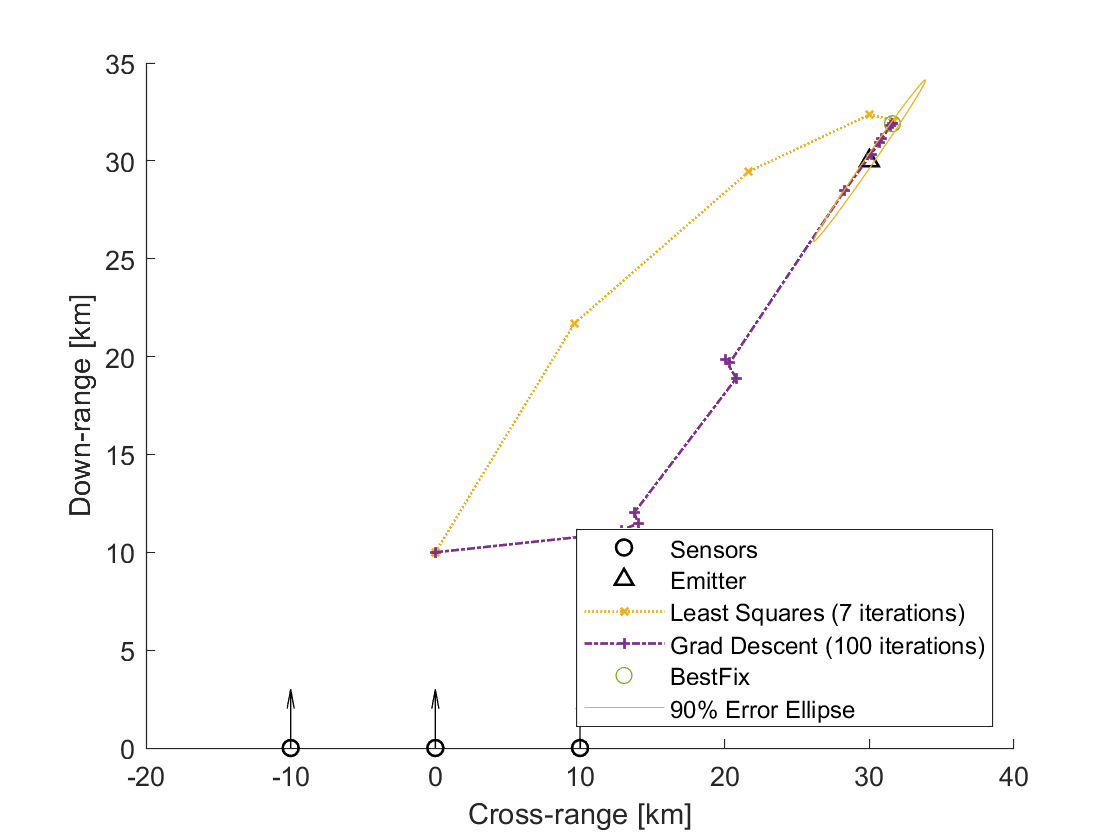

% Plot Geometry
numIterToPlot=min(20,numel(plotIndex));
figure();
hold on;
set(gca,'ydir','normal');
plot(x_sensor(1,:)/1e3,x_sensor(2,:)/1e3,'ko','DisplayName','Sensors','LineWidth',1);
hold on;
plot(x_source(1,:)/1e3,x_source(2,:)/1e3,'k^','DisplayName','Emitter','LineWidth',1);
plot(x_ls_plot(1,1:floor(numIterToPlot/2),1)/1e3,x_ls_plot(2,floor(1:numIterToPlot/2),1)/1e3,':x','DisplayName',sprintf('Least Squares (%d iterations)',plotIndex(floor(numIterToPlot/2))),'LineWidth',1,'MarkerSize',4);
plot(x_grad_plot(1,1:numIterToPlot,1)/1e3,x_grad_plot(2,1:numIterToPlot,1)/1e3,'-.+','DisplayName',sprintf('Grad Descent (%d iterations)',plotIndex(numIterToPlot)),'LineWidth',1,'MarkerSize',4);
plot(x_bf(1,1)/1e3,x_bf(2,1)/1e3,'o','DisplayName','BestFix');
set(gca,'ColorOrderIndex',3);
plot(crlb_ellipse(1,:)/1e3,crlb_ellipse(2,:)/1e3,'LineWidth',.5,'DisplayName','90% Error Ellipse');

% Draw Velocity Arrows
for idx_sensor = 1:size(x_sensor,2)
    thisX = x_sensor(:,idx_sensor);
    thisV = v_sensor(:,idx_sensor)/norm(v_sensor(:,idx_sensor));
    utils.drawArrow(thisX(1)/1e3+[0 thisV(1)]*3,thisX(2)/1e3+[0 thisV(2)]*3);
end

legend('Location','SouthEast');
% wd = 40;
% xlim([-1 1]*wd+x_source(1)/1e3/2);
grid off;
xlabel('Cross-range [km]');ylabel('Down-range [km]');

## Second Subfigure

`The ``geolocation`` error, averaged across 1,000 Monte Carlo trials, is shown here, as a function of the number of iterative steps computed. The ``RMSE``, at convergence, is just over 1 km.`

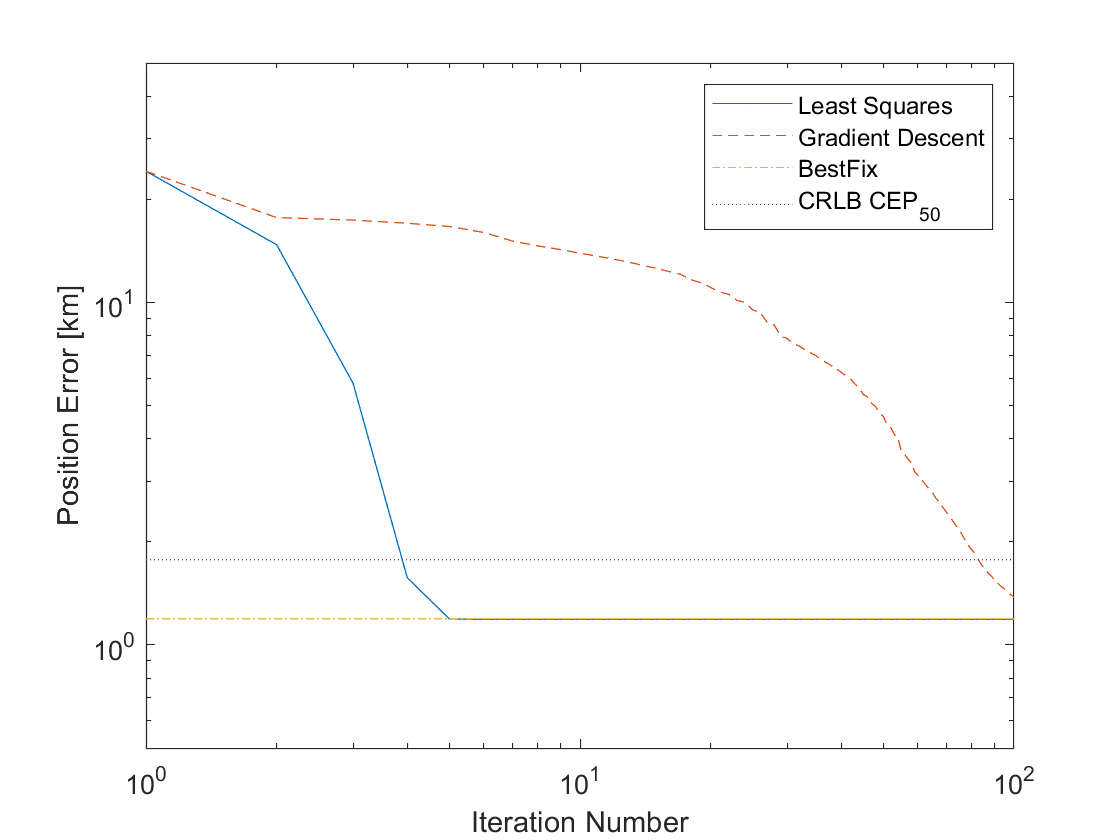

% Plot Error
figure();
plot(1:num_iters,cep50_ls,'DisplayName','Least Squares');
hold on;
plot(1:num_iters,cep50_grad,'--','DisplayName','Gradient Descent');
plot(1:num_iters,cep50_bf*ones(1,num_iters),'-.','DisplayName','BestFix');
plot(1:num_iters,crlb_cep50*ones(1,num_iters),':','DisplayName','CRLB CEP_{50}');
xlabel('Iteration Number');
ylabel('Position Error [km]');
set(gca,'yscale','log');
set(gca,'xscale','log');
legend('Location','NorthEast');
ylim([.5 50])